% function run_mm_tracking()
clc; clear; close all;

%% Paths
project_root = './';
addpath(fullfile(project_root, 'dynamics_library'));
addpath(fullfile(project_root, 'data'));

disp('✅ Paths added.');

✅ Paths added.



%% Load physical params (r, L, etc.)
S = load('mm_params.mat','phys');
phys = S.phys;

%% Controller gains (inner loop on η)
wn   = [0.8 0.8 1.2 1.2 1.0];             % natural freq per channel
zeta = [1.0 1.0 1.0 1.0 1.0];
Kp   = diag(wn.^2);
Kd   = diag(2*zeta.*wn);

%% Outer-loop (unicycle tracking) gains & limits
kxy  = 2.0;        % position gain (used in Kanayama/Samson style)
kth  = 1.5;        % heading gain
vmax = 0.6;        % [m/s]
wmax = 1.2;        % [rad/s]

outer = struct('kxy',kxy,'kth',kth,'vmax',vmax,'wmax',wmax);

%% Desired references (edit these functions to change tasks)
base_ref   = @base_ref_circle;    % reference (x_d,y_d,th_d, v_d, w_d)
arm_ref    = @arm_ref_sine;       % reference (q1_d,q2_d,q3_d, and their rates)

%% Initial state
% q = [x_m;y_m;theta_m;theta_r;theta_l;theta_1;theta_2;theta_3]
q0      = zeros(8,1);
eta0    = zeros(5,1);             % [th_r_dot; th_l_dot; th1_dot; th2_dot; th3_dot]
etad0   = zeros(5,1);             % η̇ initial
x0      = [q0; eta0; etad0];

%% Simulate
Tend = 30;
opts = odeset('RelTol',1e-8,'AbsTol',1e-10,'MaxStep',0.01);

ud.phys      = phys;
ud.Kp        = Kp; 
ud.Kd        = Kd;
ud.outer     = outer;
ud.base_ref  = base_ref;
ud.arm_ref   = arm_ref;

disp('▶️  Simulating closed-loop tracking...');

▶️  Simulating closed-loop tracking...


[t, x] = ode45(@(t,x) mm_ode_cl(t,x,ud), [0 Tend], x0, opts);
disp('✅ Simulation done.');

✅ Simulation done.


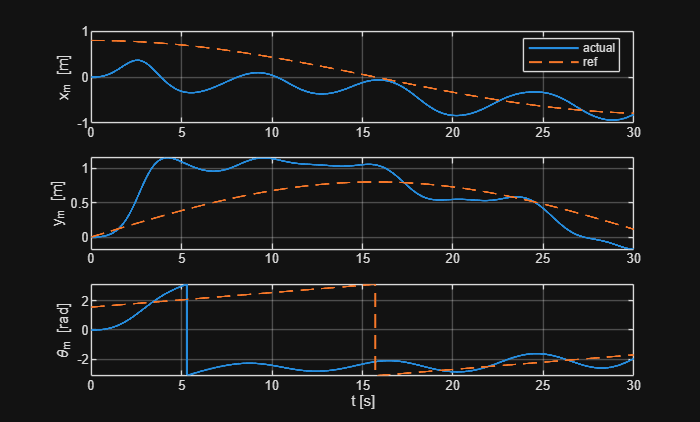


%% Unpack
nq = 8; m = 5;
q      = x(:,1:nq);
eta    = x(:,nq+(1:m));
etadot = x(:,nq+m+(1:m));

% Pull desired signals for plotting
eta_d   = zeros(numel(t), m);
etad_d  = zeros(numel(t), m);
q_base_d= zeros(numel(t),3);
for k=1:numel(t)
    [xd,yd,thd,vd,wd] = base_ref(t(k), ud.phys); %#ok<ASGLU>
    [q1d,q2d,q3d,qd1,qd2,qd3,~,~] = arm_ref(t(k)); %#ok<ASGLU>
    % build η_d and η̇_d from outer-loop mapping for plotting consistency
    [v_cmd,w_cmd] = unicycle_track(q(k,1),q(k,2),q(k,3), xd,yd,thd, vd,wd, ud.outer);
    [eta_ref, eta_dot_ref] = vw_to_wheelrates(v_cmd, w_cmd, vd, wd, ud.phys);
    eta_ref(3:5)     = [qd1; qd2; qd3];   % desired arm rates
    eta_dot_ref(3:5) = [0;0;0];
    eta_d(k,:)   = eta_ref.';
    etad_d(k,:)  = eta_dot_ref.';
    q_base_d(k,:)= [xd,yd,thd];
end

%% Plots
figure('Name','Base pose vs reference');
subplot(3,1,1); plot(t,q(:,1),'LineWidth',1.3); hold on; plot(t,q_base_d(:,1),'--','LineWidth',1.2); grid on; ylabel('x_m [m]'); legend('actual','ref');
subplot(3,1,2); plot(t,q(:,2),'LineWidth',1.3); hold on; plot(t,q_base_d(:,2),'--','LineWidth',1.2); grid on; ylabel('y_m [m]');
subplot(3,1,3); plot(t,wrapPi(q(:,3)),'LineWidth',1.3); hold on; plot(t,wrapPi(q_base_d(:,3)),'--','LineWidth',1.2); grid on; ylabel('\theta_m [rad]'); xlabel('t [s]');

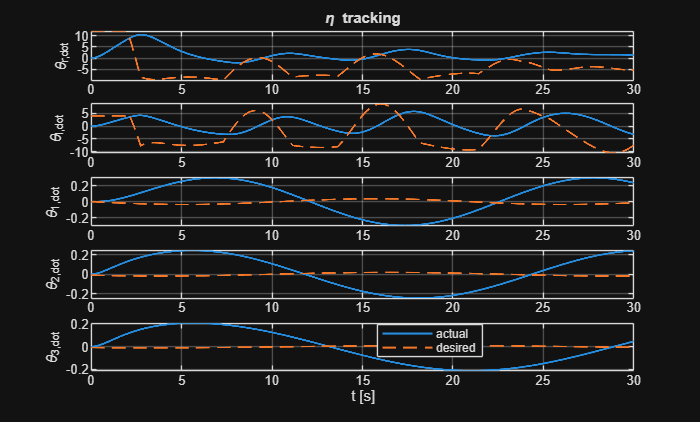


figure('Name','η tracking'); 
labels = {'\theta_{r,dot}','\theta_{l,dot}','\theta_{1,dot}','\theta_{2,dot}','\theta_{3,dot}'};
for i=1:m
    subplot(m,1,i);
    plot(t,eta(:,i),'LineWidth',1.3); hold on; plot(t,eta_d(:,i),'--','LineWidth',1.2);
    grid on; ylabel(labels{i}); if i==1, title('\eta tracking'); end
end
xlabel('t [s]'); legend('actual','desired','Location','best');

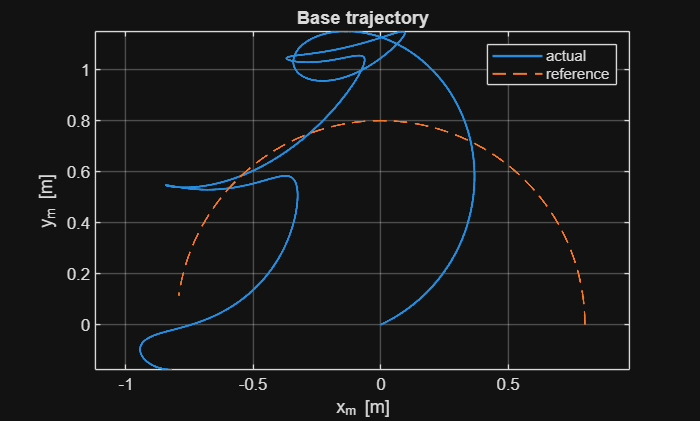


figure('Name','Planar path');
plot(q(:,1), q(:,2), 'LineWidth', 1.4); hold on; grid on; axis equal;
plot(q_base_d(:,1), q_base_d(:,2), '--','LineWidth',1.2);
xlabel('x_m [m]'); ylabel('y_m [m]'); legend('actual','reference'); title('Base trajectory');

% end


## helpers

function dx = mm_ode_cl(t, x, ud)
% x = [q(8); eta(5); etadot(5)]
% Outer loop (unicycle) -> (v,w) -> wheel-rate refs
% Inner loop (computed torque) tracks eta and etadot

%% Unpack
phys  = ud.phys;
Kp    = ud.Kp; 
Kd    = ud.Kd;
outer = ud.outer;
base_ref = ud.base_ref;
arm_ref  = ud.arm_ref;

nq = 8; m = 5;
q      = x(1:nq);
eta    = x(nq+(1:m));
etadot = x(nq+m+(1:m));

%% Desired base pose + nominal (v_d,w_d)
[xd,yd,thd,vd,wd] = base_ref(t, phys);

%% Unicycle tracking (Kanayama/Samson-style)
[v_cmd, w_cmd] = unicycle_track(q(1), q(2), q(3), xd, yd, thd, vd, wd, outer);

%% Map (v,w) -> wheel rates (η channels 1:2)
[eta_ref, eta_dot_ref] = vw_to_wheelrates(v_cmd, w_cmd, vd, wd, phys);

%% Arm references (η channels 3:5 are joint rates)
[q1d,q2d,q3d, q1dd,q2dd,q3dd, q1, q2, q3] = arm_ref(t); %#ok<ASGLU>
eta_ref(3:5)     = [q1; q2; q3];        % desired joint rates (choose rate or angle → rate)
eta_dot_ref(3:5) = [q1dd; q2dd; q3dd];  % desired joint accels for smoother inner loop

%% Model terms
R    = mm_R_fun(q);
qdot = R * eta;

M1 = mm_M1_fun(q);
C1 = mm_C1_fun(q, qdot);   % returns 5x5
G1 = mm_G1_fun(q);
B1 = mm_B1_fun(q);

persistent D_eta
if isempty(D_eta)
    S = load('data/mm_dynamics_reduced.mat','D_eta');
    D_eta = S.D_eta;
end

%% Inner-loop (computed torque / exact FL on η)
e   = (eta_ref - eta);
ed  = (eta_dot_ref - etadot);
v   = eta_dot_ref + Kd*ed + Kp*e;      % "virtual accel"

tau = B1 \ ( M1*v + (C1 + D_eta)*eta + G1 );   % u

%% Plant dynamics
etaddot = M1 \ ( B1*tau - (C1 + D_eta)*eta - G1 );
dx = [qdot; etadot; etaddot];
end
function [v,w] = unicycle_track(x,y,th, xd,yd,thd, vd,wd, prm)
% Kanayama/Samson body-frame error regulation with feedforward (vd,wd)
% prm: struct('kxy',..,'kth',..,'vmax',..,'wmax',..)

% body-frame position error
c = cos(th); s = sin(th);
exy = [ c  s; -s  c ] * ([xd;yd] - [x;y]);
e1 = exy(1); e2 = exy(2);
e3 = wrapPi(thd - th);

v = vd*cos(e3) + prm.kxy*e1;
w = wd + prm.kxy*e2 + prm.kth*e3;

% saturations
v = max(min(v, prm.vmax), -prm.vmax);
w = max(min(w, prm.wmax), -prm.wmax);
end
function [eta_ref, eta_dot_ref] = vw_to_wheelrates(v, w, vd, wd, phys)
% v,w desired; vd,wd are their time-derivatives (optional, use 0 if unknown)
% eta = [th_r_dot; th_l_dot; th1_dot; th2_dot; th3_dot]
wr = (v + phys.L*w) / phys.r;
wl = (v - phys.L*w) / phys.r;
eta_ref = [wr; wl; 0; 0; 0];

% rough time-derivatives if vd,wd provided
wr_d = (vd + phys.L*wd) / phys.r;
wl_d = (vd - phys.L*wd) / phys.r;
eta_dot_ref = [wr_d; wl_d; 0; 0; 0];
end
function [xd,yd,thd, vd,wd] = base_ref_circle(t, phys)
% Circular path of radius R with constant angular speed Ω
R = 0.8;          % [m]
Omega = 0.10;     % [rad/s]

xd =  R*cos(Omega*t);
yd =  R*sin(Omega*t);
thd= wrapPi(Omega*t + pi/2);   % tangent heading

% nominal feedforward (arc-length speed and yaw rate)
vd =  R*Omega;     % constant speed along the circle
wd =  Omega;
end
function [q1d,q2d,q3d, q1dd,q2dd,q3dd, q1,q2,q3] = arm_ref_sine(t)
% Here we define *joint rates* references and their derivatives.
% If you prefer joint angle tracking, change mapping accordingly.
A  = [0.4; 0.3; 0.25];   % [rad/s] amplitudes
w  = [0.3; 0.25; 0.2];   % [rad/s]
ph = [0.0; 0.6; 0.9];

q1 = A(1)*sin(w(1)*t+ph(1));  q1d =  A(1)*w(1)*cos(w(1)*t+ph(1));  q1dd = -A(1)*w(1)^2*sin(w(1)*t+ph(1));
q2 = A(2)*sin(w(2)*t+ph(2));  q2d =  A(2)*w(2)*cos(w(2)*t+ph(2));  q2dd = -A(2)*w(2)^2*sin(w(2)*t+ph(2));
q3 = A(3)*sin(w(3)*t+ph(3));  q3d =  A(3)*w(3)*cos(w(3)*t+ph(3));  q3dd = -A(3)*w(3)^2*sin(w(3)*t+ph(3));
end
function a = wrapPi(a)
a = mod(a+pi, 2*pi) - pi;
end
